#### Select subjects

clearvars;
filepath        = '/Users/researcher/Desktop/SWM Study/Experiments/Experiment2_2AFC/PhaseAnalysis';
subjects        = CleanDir(filepath);

fakeUI          = figure;
fakeUI.UserData = subjects;
fakeUI.Visible  =  'off';
select_labels(fakeUI,[],subjects);
waitfor(findall(0,'Name','Select Labels'),'BeingDeleted','on');
subjects        = fakeUI.UserData;
close(fakeUI);

layout          = 'C:\Users\User\Documents\GitHub\Deci\Function\Gen_Fun\easycap_rob_eye.mat';

#### Choose trials

correcttrials = true;

if correcttrials == true
    version = [];
    for subs = 1:length(subjects)
        director = [filepath filesep subjects{subs} filesep subjects{subs} version]; 
        load([director '_ppc2.mat'],'data');
        load([director '_trialrej.mat'],'saminfo');
        correct{subs} = (data.trialinfo(:,9) == 1 & data.trialinfo(:,10) == 1);
        clear data
        correct{subs} = correct{subs}(saminfo);
        clear saminfo
    end
end


#### Rotating data for cross-subject normalization

version = [];
showlaplace     = false;
showhilbert     = false;
correcttrials   = true;

if showlaplace == true
    version = [version '_laplace'];
end
if showhilbert == true
    version = [version '_hilbert'];
end

if correcttrials == true
    load('/Users/researcher/Desktop/SWM Study/Experiments/Experiment2_2AFC/CorrectNonRejectedTrials.mat');
end

% Run a loop across subjects
for subs = 1:length(subjects)
    
    % load the phase difference data
    director    = [filepath filesep subjects{subs} filesep subjects{subs} version]; 
    stimlocked  = load([director '_lock1_phase.mat'],'dhist','dav','cellperms');  % dhists are chan*chan*timeperiod_of_interest*trial matrices
    d3locked    = load([director '_lock2_phase.mat'],'dhist','dav','cellperms');
    
    % sort channel labels according to position on the head
    stimlocked  = sortcells(stimlocked);
    d3locked    = sortcells(d3locked); 

    % choose correct trials only
    if correcttrials == true
        stimlocked.dhist    = stimlocked.dhist(:,:,:,correct{subs});
        d3locked.dhist      = d3locked.dhist(:,:,:,correct{subs});     
    end

    % initialize a matrix to store the angle in radian that should be
    % subtracted
    subcoef = nan(size(stimlocked.dhist,1),size(stimlocked.dhist,2));
    
    % For each subject, project the D1 distribution into the complex space,
    % average complex D1s and determine the mean angle
    
    for xi = 1:size(stimlocked.dhist,1)
        for yi = 1:size(stimlocked.dhist,2)
            
            % subtraction angle: the time-average, cross-trial phase
            % difference distribution is projected to the complex unit
            % circle, averaged, and the angle of the average vector is
            % taken. The resultant angle is multipled by -1 to reflect
            % subtraction.
            subcoef(xi,yi) = -1*angle(mean(exp(1i.*(stimlocked.dhist(xi,yi,1,:)))));
            
            % the angle rotation is performed in the complex plane again.
            % The subtraction angle is projected in the complex plane, the
            % angle distrubutions are projected in the complex plane, and
            % the two sets of vectors are multiplied [z' = z.*exp(itheta)]
            % Then the angle is taken again.
            % Note that the same angle is subtracted from D1, D2, D3 and D4 distributions
            rotated(subs).stimlock.d1(xi,yi,:) = angle(exp(1i.*stimlocked.dhist(xi,yi,1,:)).*(exp(1i*subcoef(xi,yi))));
            rotated(subs).stimlock.d2(xi,yi,:) = angle(exp(1i.*stimlocked.dhist(xi,yi,2,:)).*(exp(1i*subcoef(xi,yi))));
            rotated(subs).d3lock.d3(xi,yi,:)   = angle(exp(1i.*d3locked.dhist(xi,yi,1,:)).*(exp(1i*subcoef(xi,yi))));
            rotated(subs).d3lock.d4(xi,yi,:)   = angle(exp(1i.*d3locked.dhist(xi,yi,2,:)).*(exp(1i*subcoef(xi,yi))));
                        
            % store original data in a similar format for ease
            original(subs).stimlock.d1(xi,yi,:) = stimlocked.dhist(xi,yi,1,:);
            original(subs).stimlock.d2(xi,yi,:) = stimlocked.dhist(xi,yi,2,:);
            original(subs).d3lock.d3(xi,yi,:)   = d3locked.dhist(xi,yi,1,:);
            original(subs).d3lock.d4(xi,yi,:)   = d3locked.dhist(xi,yi,2,:);

        end
    end
    % channel labels
    rotated(subs).cellperms     = stimlocked.cellperms;
    original(subs).cellperms    = stimlocked.cellperms;
    
    % clear variables that overlap across subjects
    clear stimlocked d3locked
end


#### Concatenate rotated data across subjects

% Check if the rotation has been performed on the data
if ~exist('rotated','var')
    error('Run section on rotating data first.');
end

% initialize a structure where the data concatenated across subjects will
% be stored
concat.stimlock.d1 = [];
concat.stimlock.d2 = [];
concat.d3lock.d3 = [];
concat.d3lock.d4 = [];

% perform the concatenation along the 3rd dimension (trial); first two
% dimensions are channels
for subs = 1:length(subjects)
   concat.stimlock.d1   = cat(3,concat.stimlock.d1,rotated(subs).stimlock.d1);
   concat.stimlock.d2   = cat(3,concat.stimlock.d2,rotated(subs).stimlock.d2);
   concat.d3lock.d3     = cat(3,concat.d3lock.d3,rotated(subs).d3lock.d3);
   concat.d3lock.d4     = cat(3,concat.d3lock.d4,rotated(subs).d3lock.d4);
end

% channel labels
concat.cellperms = rotated(1).cellperms{1};

#### WW-test on concatenated data

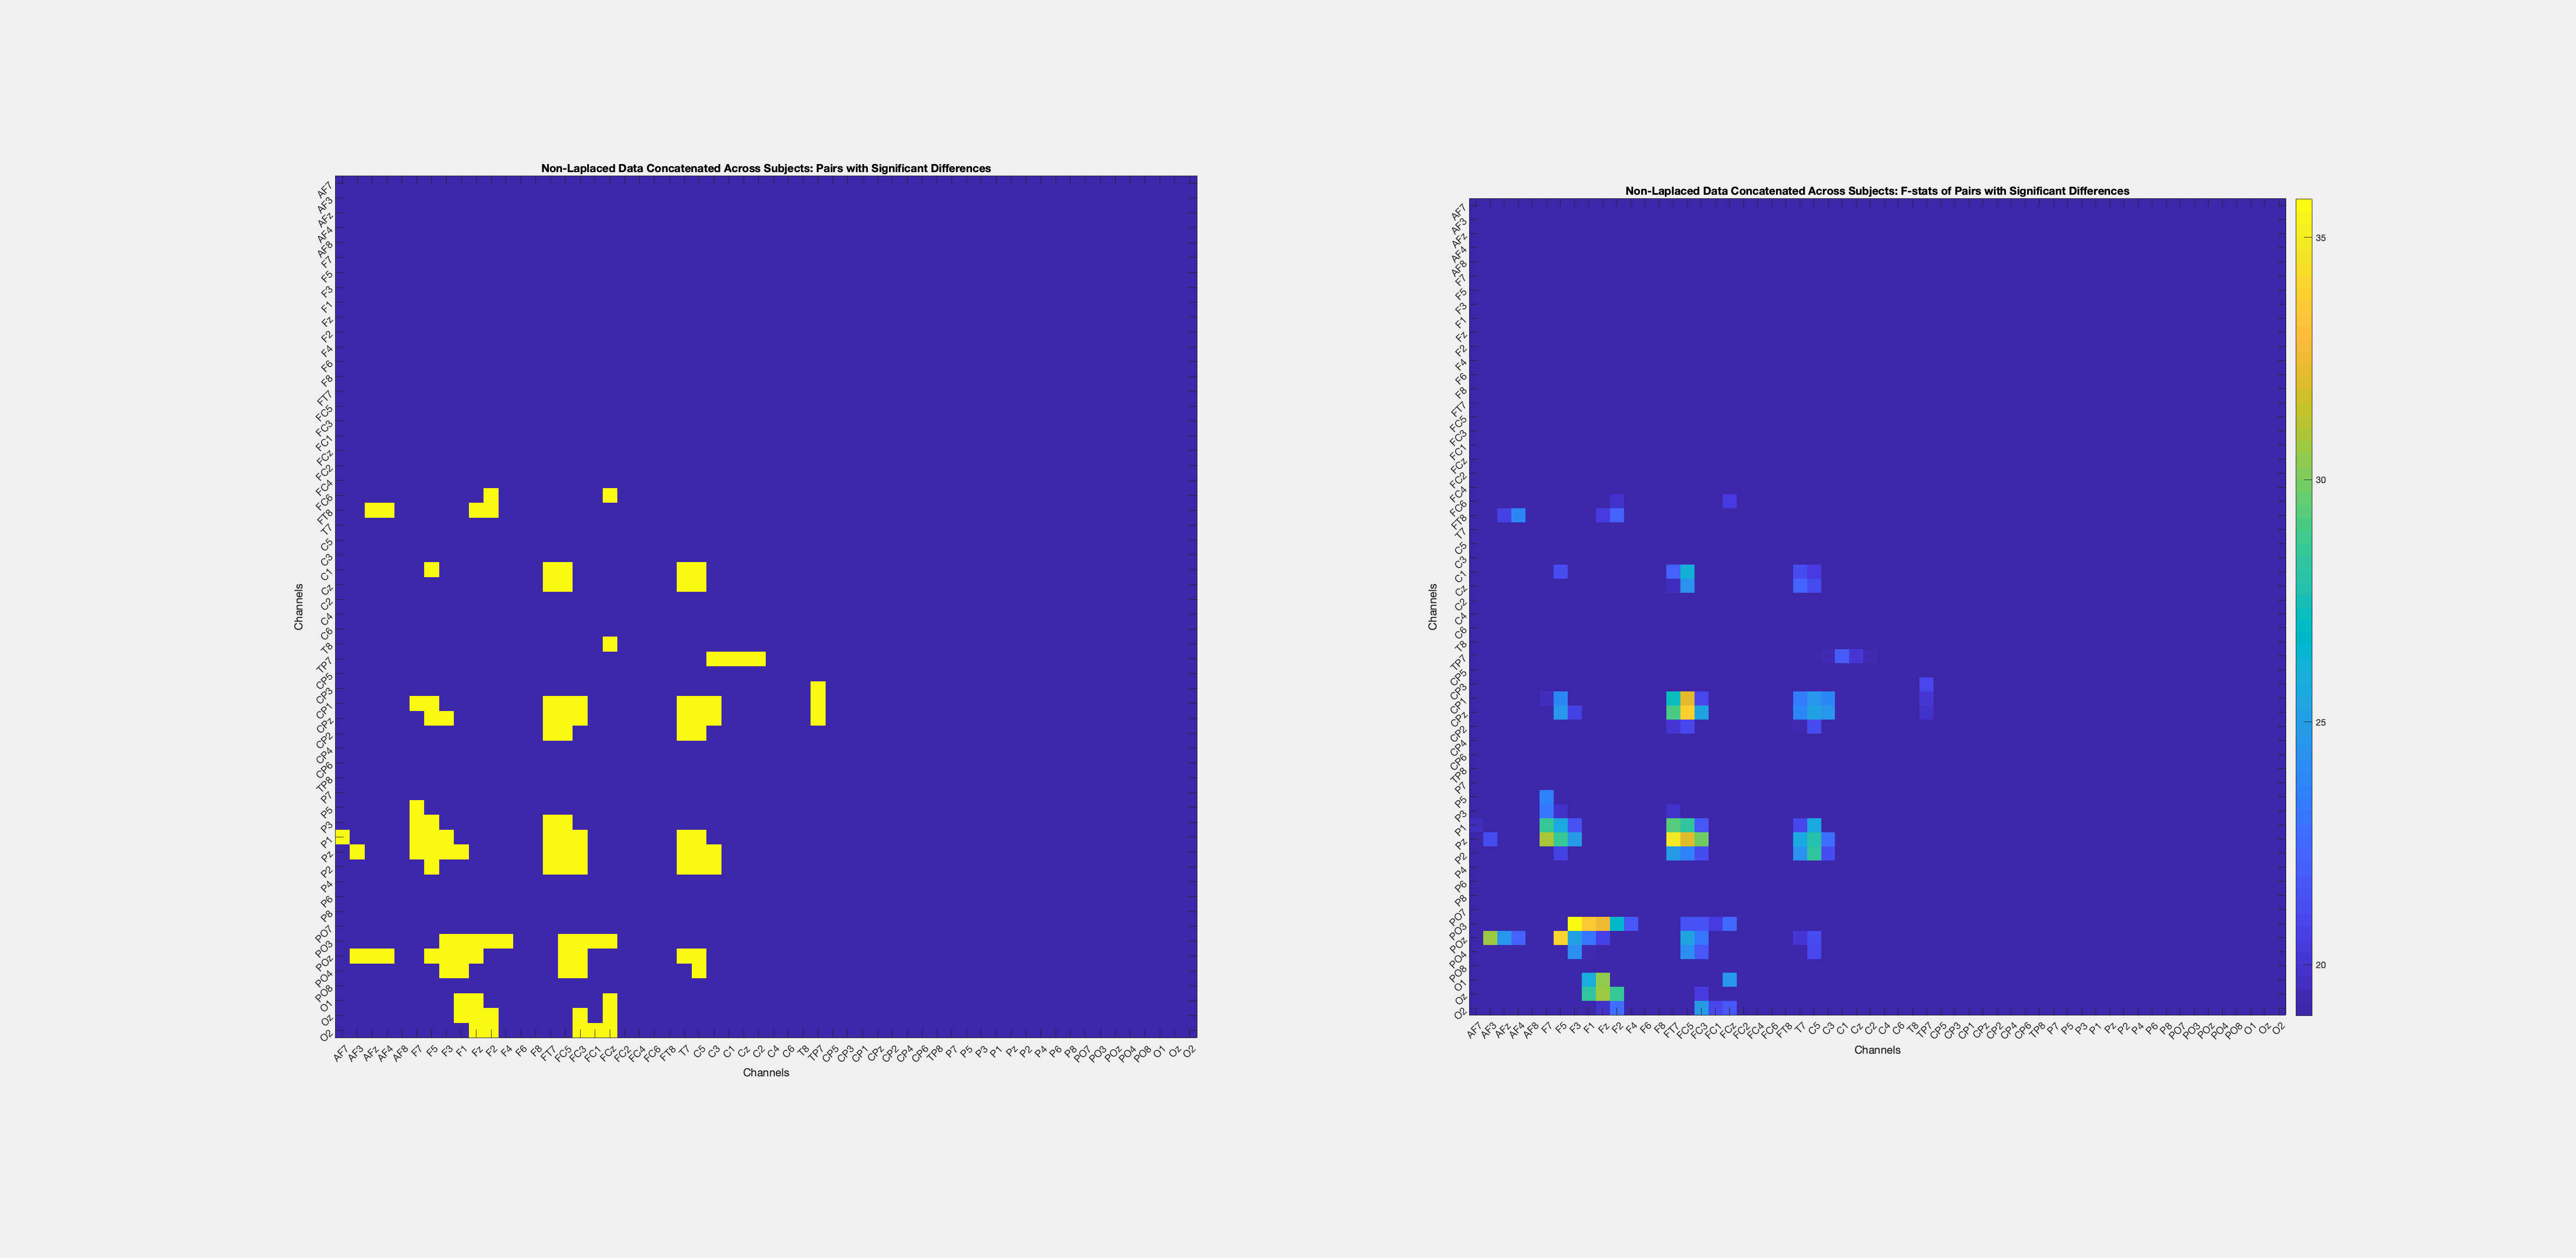

% for every channel pair, compare the time-average, cross-trial
% distrubutions in the two delay periods using the cicrular Watson-Williams
% test, and store the p-value, F-statistic, variance table, and the
% resultant vector length that determines the validity of the test
for chani = 1:size(concat.stimlock.d1,1)
    for chanj = 1:size(concat.stimlock.d1,2)
 
        [concat.ww.p(chani,chanj), concat.ww.f(chani,chanj), concat.ww.tab{chani,chanj},...
            concat.ww.rw(chani,chanj)] = circ_wwtest((concat.stimlock.d1(chani,chanj,:)),(concat.d3lock.d3(chani,chanj,:)));
    
    end
end 
    
% Prep another structure where we will do modifications to plot as per
% requirements and validity of the test
vplot = ones(size(concat.ww.p));
 
% Retain only one diagonal matrix: as comparisons are symmetric, only plot
% one diagonal matrix for ease of visualization
if size(vplot,1) == size(vplot,2)
    for i = 1:size(vplot,1)
        vplot(i,i:end) = 0;
    end
end
    
% Perform Bonferroni correction, and only consider the values for which the
% cWW test was valid
vplot((concat.ww.p >= (0.05/(58*58))) | (concat.ww.rw < 0.45)) = 0;
 
% Plotting
f = figure('units','normalized','outerposition',[0 0 1 1]);
subplot(1,2,1)
imagesc(vplot);
xticks(1:length(concat.cellperms));
yticks(1:length(concat.cellperms));
xticklabels(concat.cellperms);
yticklabels(concat.cellperms);
xlabel('Channels');
ylabel('Channels');
axis square
xtickangle(45)
ytickangle(45)
title('Non-Laplaced Data Concatenated Across Subjects: Pairs with Significant Differences');

subplot(1,2,2)
fstatplot = concat.ww.f;
fstatplot(vplot==0) = NaN;
imagesc(fstatplot);
xticks(1:length(concat.cellperms));
yticks(1:length(concat.cellperms));
xticklabels(concat.cellperms);
yticklabels(concat.cellperms);
xlabel('Channels');
ylabel('Channels');
axis square
xtickangle(45)
ytickangle(45)
title('Non-Laplaced Data Concatenated Across Subjects: F-stats of Pairs with Significant Differences');
colorbar;

f.Visible = 'on';

#### Validation - Plot histograms of significant pairs

% determine the label combinations that were significant
sigpairs = {};
for xi = 1:size(vplot,1)
    for yi = 1:size(vplot,2)
        if vplot(xi,yi) == 1
            sigpairs{end+1} = {cell2mat(concat.cellperms(xi)) cell2mat(concat.cellperms(yi))};
        end
    end
end

% Colormap
map = brewermap(4,'Set1');

polars = figure('units','normalized','outerposition',[0 0 1 1]);
for i = 1:length(sigpairs)
    chanpair = sigpairs{i};

    d1hist = concat.stimlock.d1(ismember(concat.cellperms,chanpair{1}),ismember(concat.cellperms,chanpair{2}),:);
    d3hist = concat.d3lock.d3(ismember(concat.cellperms,chanpair{1}),ismember(concat.cellperms,chanpair{2}),:);

    subplot(4,5,i);
    f1 = polarhistogram(d1hist,'facecolor',map(1,:),'facealpha',.5,'edgecolor','none');
    hold on;
    f3 = polarhistogram(d3hist,'facecolor',map(3,:),'facealpha',.5,'edgecolor','none');
    hold on;
    if mod(i,5) == 0
        legend([f1 f3],{'D1','D3'});
    end
    title([chanpair{1} ' - ' chanpair{2}])
    set(gca,'FontSize',14)

    clear d1hist d3hist
end
polars.Visible = 'on';

#### Paired t-test  across subjects on mean phase difference angles

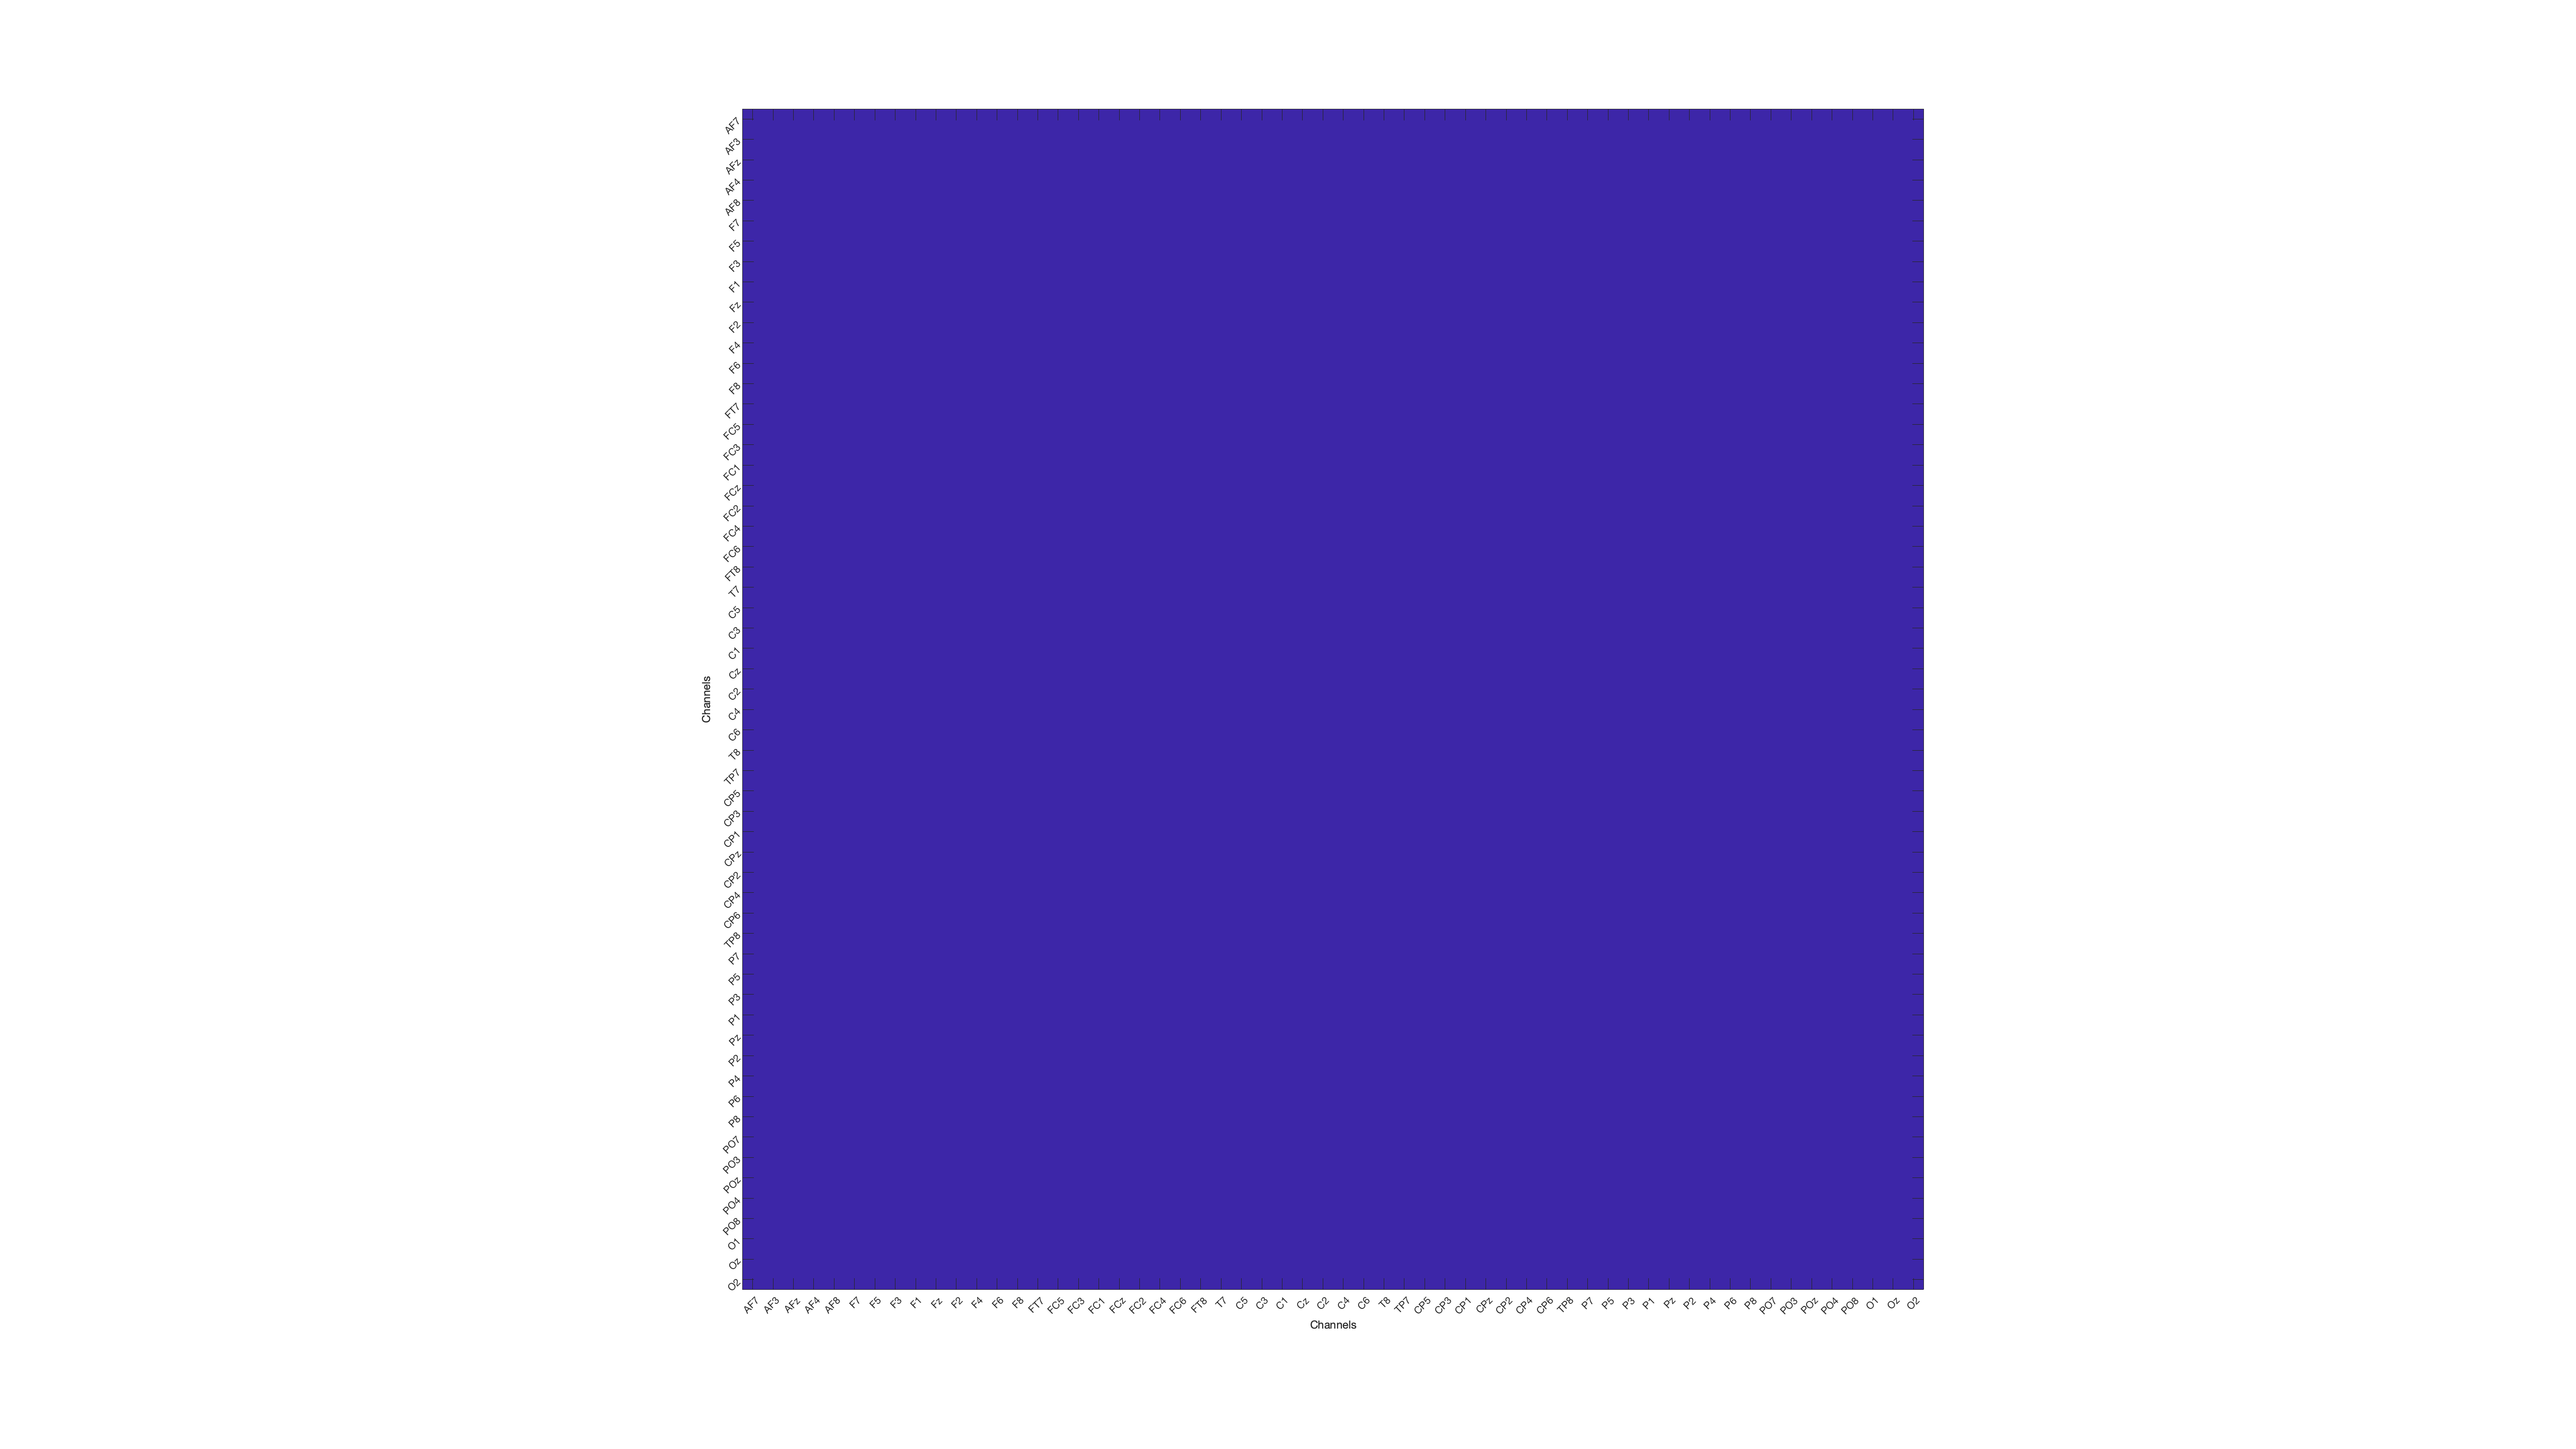


if ~exist('rotated','var')
    error('Run section on rotating data first.');
end
for subs = 1:length(subjects)
   for xi = 1:size(rotated(subs).stimlock.d1,1)
       for yi = 1:size(rotated(subs).stimlock.d1,2)
           d1av(subs,xi,yi) = angle(mean(exp(1i.*(rotated(subs).stimlock.d1(xi,yi,:))))); % this will be an internal check to confirm rotation happened properly. These values should be zero.
           d3av(subs,xi,yi) = angle(mean(exp(1i.*(rotated(subs).d3lock.d3(xi,yi,:)))));
       end
   end
   
end

for xi = 1:size(d1av,2)
   for yi = 1:size(d1av,3)
       [h(xi,yi),p(xi,yi),~,stats{xi,yi}] = ttest(d1av(:,xi,yi),d3av(:,xi,yi));
   end
end

for i = 1:size(p,1)
    p(i,i:end)    = NaN;
end
 
figure('units','normalized','outerposition',[0 0 1 1]);
imagesc(p<(0.05/(58*58)))
xticks(1:length(rotated(1).cellperms{1}));
yticks(1:length(rotated(1).cellperms{2}));
xticklabels(rotated(1).cellperms{1});
yticklabels(rotated(1).cellperms{2});
xlabel('Channels');
ylabel('Channels');
axis square
xtickangle(45)
ytickangle(45)

#### Paired t-test  across subjects on variance of phase difference angles


if ~exist('rotated','var')
    error('Run section on rotating data first.');
end
for subs = 1:length(subjects)
   for xi = 1:size(rotated(subs).stimlock.d1,1)
       for yi = 1:size(rotated(subs).stimlock.d1,2)
           d1var(subs,xi,yi) = circ_var(rotated(subs).stimlock.d1(xi,yi,:)); % this will be an internal check to confirm rotation happened properly. These values should be zero.
           d3var(subs,xi,yi) = circ_var(rotated(subs).d3lock.d3(xi,yi,:));
       end
   end
   
end

for xi = 1:size(d1av,2)
   for yi = 1:size(d1av,3)
       [h(xi,yi),p(xi,yi),~,stats{xi,yi}] = ttest(d1var(:,xi,yi),d3var(:,xi,yi));
   end
end

for i = 1:size(p,1)
    p(i,i:end)    = NaN;
end
 
figure('units','normalized','outerposition',[0 0 1 1]);
imagesc(p<(0.05/(58*58)))
xticks(1:length(rotated(1).cellperms{1}));
yticks(1:length(rotated(1).cellperms{2}));
xticklabels(rotated(1).cellperms{1});
yticklabels(rotated(1).cellperms{2});
xlabel('Channels');
ylabel('Channels');
axis square
xtickangle(45)
ytickangle(45)

#### Determining circular variance of the two delay periods

version = [];
showlaplace     = false;
showhilbert     = false;
if showlaplace == true
    version = [version '_laplace'];
end
if showhilbert == true
    version = [version '_hilbert'];
end

% Run a loop across subjects
for subs = 1:length(subjects)
    director = [filepath filesep subjects{subs} filesep subjects{subs} version]; 
    stimlocked  = load([director '_lock1_phase.mat'],'dhist','dav','cellperms');  % dhists are chan*chan*timeperiod_of_interest*trial matrices
    d3locked    = load([director '_lock2_phase.mat'],'dhist','dav','cellperms');
    
    % sort channel labels according to position on the head
    stimlocked  = sortcells(stimlocked);
    d3locked    = sortcells(d3locked); 
    
    for xi = 1:size(stimlocked.dhist,1)
        for yi = 1:size(stimlocked.dhist,2)
            d1var(subs,xi,yi) = circ_var(stimlocked.dhist(xi,yi,1,:));
            d3var(subs,xi,yi) = circ_var(d3locked.dhist(xi,yi,1,:));
        end
    end
end

for xi = 1:size(d1var,2)
   for yi = 1:size(d1var,3)
       [h(xi,yi),p(xi,yi),~,stats{xi,yi}] = ttest(d1var(:,xi,yi),d3var(:,xi,yi));
   end
end
        
figure('units','normalized','outerposition',[0 0 1 1]);
imagesc(p<(0.05/(58*58)))
% imagesc(p<(1e-04))
xticks(1:length(stimlocked.cellperms{1}));
yticks(1:length(stimlocked.cellperms{2}));
xticklabels(stimlocked.cellperms{1});
yticklabels(stimlocked.cellperms{2});
xlabel('Channels');
ylabel('Channels');
axis square
xtickangle(45)
ytickangle(45)
    